# Lesson 3

Originally written by Brenda So and Cory Nezin.

# Objective

After this class, you should be able to:

- Understand linear and logical indexing

- Know how to write anonymous and normal functions

- Understand how plotting works

# Review on Basic Indexing

Let's start off with some basic indexing we've seen earlier. Remember:

- We use curly brackets instead of square brackets for indexing.

- MATLAB is 1 indexed, instead of 0 indexed.

x = [16 5 9 4 2 11 7 14];
x(:);    
x(1);    
x(2:5);
x(end-1);

x([1 3 5 7])    % Indexing the 1,3,5,7th element in x

ans =     16     9     2     7


x(1:2:7)        % You're basically doing the same thing as above

ans =     16     9     2     7


x([5:8 1:4])    

ans =      2    11     7    14    16     5     9     4


x(1:4) = 40

x =     40    40    40    40     2    11     7    14



A = [16 2 3 13; 5 11 10 8; 9 7 6 12; 4 14 15 1]

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


A(1,4)    % Extract the element in row 1, column 4

ans = 13

You can also extend this notation into a more general case, where one or both of the rows and columns can be vectors:

A(1:3, 1:2)

ans =     16     2
     5    11
     9     7


A(end, :)

ans =      4    14    15     1


A(:, 3)

ans =      3
    10
     6
    15


However, indexing with 2 subscripts has its limitations. For example, suppose you want to extract the elements (2,1), (3,2), (4,4) from A. One might intuitively think to do the following, but it wouldn't work!

A([2 3 4],[1 2 4])    % It doesn't work! WHY?

ans =      5    11     8
     9     7    12
     4    14     1


 The picture below illustrates what is actually happening:

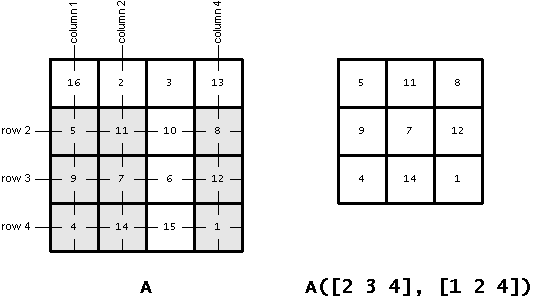

# Linear indexing

When you index into A with only 1 subscript, MATLAB automatically flattens the matrix into one column vector:

A(:)

ans =     16
     5
     9
     4
     2
    11
     7
    14
     3
    10


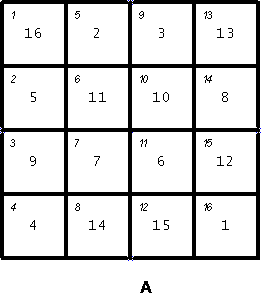

A(14)    

ans = 8

Consider the aforementioned problem again: To index (2,1), (3,2), (4,4), you'll need to do 

A([2 7 16])

ans =      5     7     1


But luckily enough, MATLAB has a function that would calculate the linear index for you!

ind = sub2ind(size(A),[2 3 4],[1 2 4])

ind =      2     7    16


# Logical Operators

Before we discuss logical indexing, we need to address the idea of logic in MATLAB. You should all know what *and*, *or*, and *not* is from DLD. In MATLAB, you can apply such concepts for logical arrays. Logical arrays are arrays of 0(false) and 1(true). Note that an array of 0 and 1 might not necessary be a logical array, but using the function *logical* you can convert a normal array into a logical array.

B = eye(4);
C = logical([1 1 1 1; 1 0 0 0; 1 0 0 0; 1 0 0 0]);
D = true(2,5)   % creates a 2-by-5 logical matrix with all elements = 1.

D = 2×5 logical array
   1   1   1   1   1
   1   1   1   1   1


islogical(B)    % returns whether B is a logical array or not.

ans = logical
   0


islogical(C)

ans = logical
   1


B_prime = logical(B);   % converts B into a logical array.
islogical(B')

ans = logical
   0



B & C;      % and(B,C) is equivalent to B&C
B | C;      % or(B,C) is equivalent to B|C
~(B & C);   % not(and(B,C)) is equivalent to ~(B&C)
not(B & C); % you can use both representations intermittenly 
xor(B,C);   % only one way to xor logicals

**Note 1:** *not(2)* and *not(-2)* both give you one, only *not(0)* gives you zero. 

**Note 2:** The logical operators above (&, |, ~, and *xor*) also work on non logical arrays. However their output will always be a logical 1 or 0.

# Logical Indexing

Another indexing variation, *logical indexing*, has proven to be both useful and expressive. In logical indexing, you use a single, logical array for the matrix subscript. MATLAB extracts the matrix elements corresponding to the nonzero values of the logical array. The output is always in the form of a column vector. 

The expression A > 12 creates a logical array, the same size as A, where each element would show 1 if the expression evaluates to true, else 0, because the expression is false:

A > 12

ans = 4×4 logical array
   1   0   0   1
   0   0   0   0
   0   0   0   0
   0   1   1   0


You can then use this as an index to A! For example, `A(A > 12)` extracts all the elements of `A` that are greater than 12. 

A(A > 12)

ans =     16
    14
    15
    13


And if you want to find the indices where A > 12, you can write

[r,c] = find(A > 12)

r =      1
     4
     4
     1


c =      1
     2
     3
     4


To get back the locations in the matrix, we can call:

[r2,c2] = ind2sub(size(A), find(A>12))

r2 =      1
     4
     4
     1


c2 =      1
     2
     3
     4



isequal(r,r2);
isequal(c,c2);

# Example of Vectorization

Often you will want to find how many elements in your vector are greater than a certain threshold (one common application is communication theory, when you are trying to distinguish between different received bit values i.e. If X > 0.5, the bit that was transmitted was a 1, else the bit that was transmitted was a 0.

X = exprnd(1, 2000000, 1);

% using for loops
tic
count = 0;
for j = 1:length(X)
    if X(j) > 0.75
        count = count + 1;
    end
end
toc

Elapsed time is 5.318309 seconds.


% using vectorization
tic
count2 = sum(X(:) > 0.75);
toc

Elapsed time is 0.009496 seconds.


isequal(count, count2)

ans = logical
   1


# Functions

In MATLAB, there are 2 types of functions: anonymous functions and 'regular' functions. Writing functions is very important in MATLAB. Namely, if you have 10 lines of code that is going to be applied 1000 times with different variables names, you shouldn't have to write 10,000 lines of code!

**Note: **Functions can return one or more values.

# Anonymous Functions

Anonymous functions are labeled as a variable and can only consist of one expression. 

s = @(x) sin(1./x); % an anonymous function called 's'.

y = s(pi);
y_range = s(0:0.01:2*pi);

# Normal functions

The second type of functions that can be made in MATLAB resemble functions from other languages. Normally, functions are declared in another file and outside of this file, the only function that we can use is the one that has the same name as that file. Therefore if you wanted to write multiple functions that will be used in a different file, each one of those functions will need to have its own file, with the file name equal to the function name.

MATLAB also has 'local' functions, which exist at the end of a file and that can be called only inside that same file. In this case, the file name can be called whatever. Therefore local functions cannot be used outside of the file that they appear in. 

For regular functions that you want to use in other files, you must make sure that your file name matches the function you want. Try calling the function in *lesson3_fn_demo.m* to to find out what happens otherwise.

# Basics of Plotting

We will go over some of the many plotting features of MATLAB next week. However here we will just go over the basics behind the functions *figure* and *hold on, *so that you can do the homework.

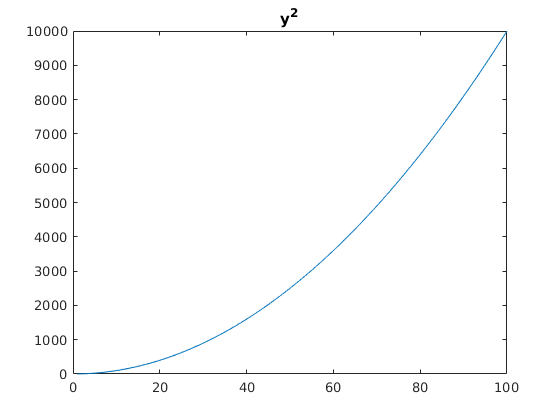

x = 1:100;
y1 =  x.^2;
y2 = -x.^2;
y3 =  x.^3;

figure
plot(x,y1)
title('y^2')

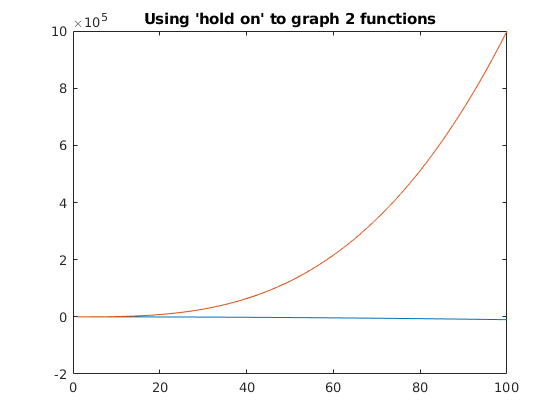

figure
plot(x,y2)
hold on     % allows you to plot multiple plots on the same figure
plot(x,y3)
title("Using 'hold on' to graph 2 functions")

# Examples:

1. **Find the Peak:** Create a matrix with magic(5) and find the maximum of each row. Afterwards, set all numbers, except for the peak, to be zero. A hint would be to use *help max* to find out how to take the maximum of each row.

% WRITEME: Find the Peak
% STEP 1 : Create a magic matrix of size 5 x 5, store it in A
% STEP 2 : Create a column vector b, which stores the max of each row in A
% STEP 3 : Use the built-in find function, find the index at which A is equal to b, and store it as c
% STEP 4 : Create another matrix of size 5 x 5, initialize all elements to 0 with built-in zeros function, store it in C
% STEP 5 : Set the elements in C where its index in A gives you the max to be b

2. **Matrix Wrap Around:** Write a function which given a vector of distinct points $xVec=\text{ }\left\lbrack x_1 ,x_{2\text{ }} ,\ldotp \ldotp \ldotp ,x_N \right\rbrack$and a point $x$, finds the index $i^\ast $ such that $x_{i^\ast  } \le x$ and$x_{\left(i^\ast  +1\right)} >x$. You may assumed that the points are ordered and distinct, $x_i <x_{i+1} ,1\le i\le N-1$, but you should not assume that the points are equidistantly spaced. You may also assume that $x_1 \le x\le x_n$. You can do either anonymous or general function. Hint: Use the built-in function* find *and *max*.

Save the function in the file *findPivot.m*, and run your function for two cases: $x=\frac{1}{\sqrt{2}}$ and $xVec=0\ldotp 01\ast \left\lbrack 0:100\right\rbrack$; $x=0\ldotp 5$ and $xVec=sort\left(rand\left(1,100\right)\right)$

% WRITEME: Matrix Wrap Around : For anonymous functions